sample_values = double_stunted_gaussian_inverse_gamma(rand(1,1e3),6/10,1/20);
x = 2;

[player_struct,profit] = mark_1_gambling_system(sample_values,x,'moneyline_tolerance',1)

player_struct = 1×1000 struct array with fields:
    player_number
    player_probability
    bet_amount
    peer2peer_win_condition
    peer2peer_bet_amount
    pot
    matched_player
    moneyline_win_condition
    moneyline_palpha
    moneyline_pbeta
    moneyline_bet_amount
    remaining_bet_amount


profit = 33.3594

How Much Arbitrage is Effectively Generated (effective as 'in practical', not 'in the optimal sense')

num_samples = length(sample_values);
focal_outcomes = zeros(1,num_samples);
compliment_outcomes = zeros(1,num_samples);

for index = 1:num_samples

    if player_struct(index).peer2peer_win_condition
        focal_outcomes(index) = player_struct(index).pot - player_struct(index).peer2peer_bet_amount;
        compliment_outcomes(index) = -player_struct(index).peer2peer_bet_amount;
    else
        focal_outcomes(index) = -player_struct(index).peer2peer_bet_amount;
        compliment_outcomes(index) = player_struct(index).pot - player_struct(index).peer2peer_bet_amount;
    end

    if ~isnan(player_struct(index).moneyline_win_condition)

        if player_struct(index).moneyline_win_condition
            alpha = 100*player_struct(index).moneyline_palpha/(1-player_struct(index).moneyline_palpha);
            focal_outcomes(index) = focal_outcomes(index) + 100/alpha*player_struct(index).moneyline_bet_amount;
            compliment_outcomes(index) = compliment_outcomes(index) - player_struct(index).moneyline_bet_amount;
        else
            beta = 100*player_struct(index).moneyline_pbeta/(1-player_struct(index).moneyline_pbeta);
            focal_outcomes(index) = focal_outcomes(index) - player_struct(index).moneyline_bet_amount;
            compliment_outcomes(index) = compliment_outcomes(index) + beta/100*player_struct(index).moneyline_bet_amount;
        end
    end
end

moneyline_win_conditions = [player_struct(:).moneyline_win_condition];
peer2peer_win_conditions = [player_struct(:).peer2peer_win_condition];

num_arbitrage_opportunitiess = sum( moneyline_win_conditions(~isnan(moneyline_win_conditions)) == ...
    peer2peer_win_conditions(~isnan(moneyline_win_conditions)) )

num_arbitrage_opportunitiess = 244


arbitrage_amounts = min(max(focal_outcomes,0),max(compliment_outcomes,0));
num_arbitrages = length(arbitrage_amounts(arbitrage_amounts~=0))

num_arbitrages = 0

sum_arbitrages = sum(arbitrage_amounts)

sum_arbitrages = 0

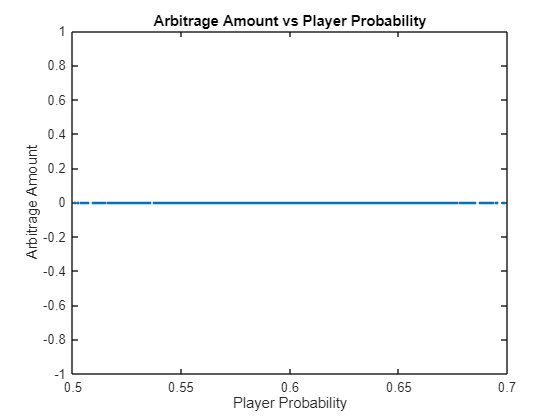


plot([player_struct(:).player_probability],arbitrage_amounts,'LineStyle','none','Marker','.')
xlabel('Player Probability')
ylabel('Arbitrage Amount')
title('Arbitrage Amount vs Player Probability')


% Quick Double Check of Profit

-sum(focal_outcomes)

ans = 33.3460

-sum(compliment_outcomes)

ans = 33.3531

profit

profit = 33.3594

% Off By Less Than A Basis Point

A Quick Digression into Expected Value

expected_values = [player_struct(:).player_probability].*focal_outcomes + (1-[player_struct(:).player_probability]).*compliment_outcomes;

variances = [player_struct(:).player_probability].*(focal_outcomes-expected_values).^2 + ...
            (1-[player_struct(:).player_probability]).*(compliment_outcomes-expected_values).^2;

total_expected_value = sum(expected_values)

total_expected_value = 30.6645

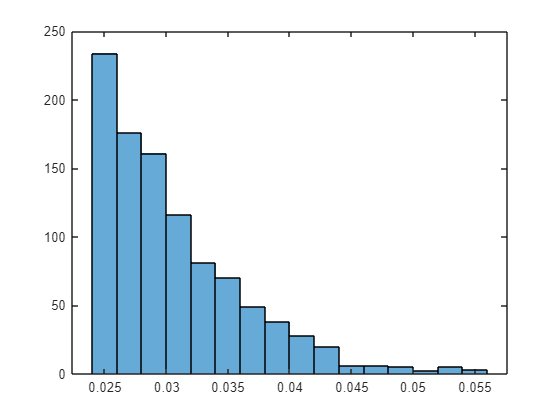


histogram(expected_values)

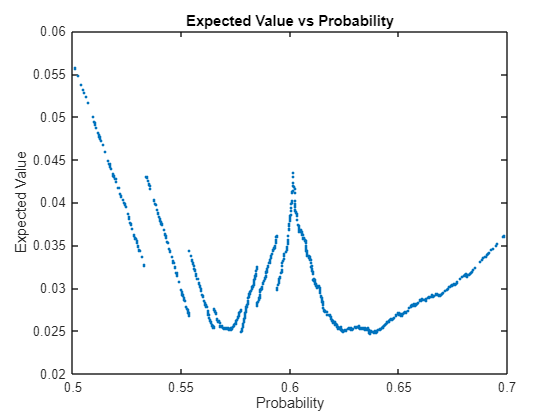


plot([player_struct(:).player_probability],expected_values,'LineStyle','none','Marker','.')
xlabel('Probability')
ylabel('Expected Value')
title('Expected Value vs Probability')

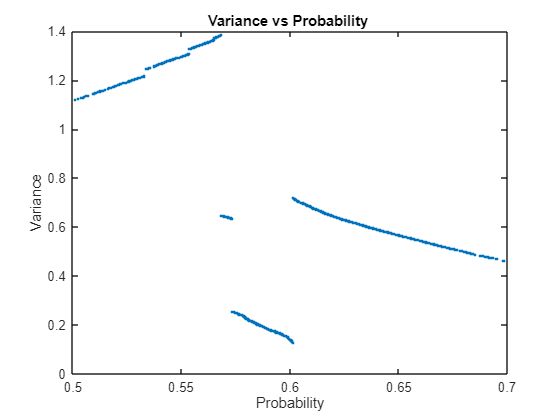


plot([player_struct(:).player_probability],variances,'LineStyle','none','Marker','.')
xlabel('Probability')
ylabel('Variance')
title('Variance vs Probability ')

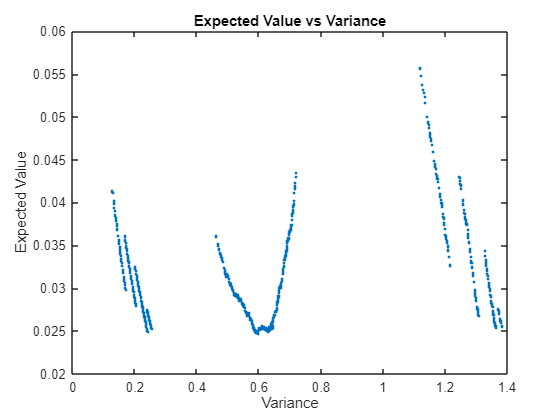


plot(variances,expected_values,'LineStyle','none','Marker','.')
xlabel('Variance')
ylabel('Expected Value')
title('Expected Value vs Variance')


% I would love to compare the plots from the Mark 1 to the plots of a
% solely Peer to Peer system